
%close all;

save_data = 1;
maindir = '\\Artemis-pc\Data\2026-08-21\';
%x = [0:1:20]*13.7;
% x = [42 59 70 85 99 ...
%     113 128 140 153 170 ...
%     180 194 204 217 228 ...
%     247 251 273 285 298 310]';   % um
% y = [61 61 62 61 61 ...
%     61 62 61 62 62 ...
%     62 62 57 44 28 ...
%     20 18 18 19 20 20]';
%x = 158+[1:15]*13.7;
x = xx([1:end],1);
y = xx([1:end],2);

xmin = min(x);
xmax = max(x);
ymin = 0;
ymax = max(y)*1.17;

%load('\\Artemis-pc\Data\2026-06-02\A_M1.mat');


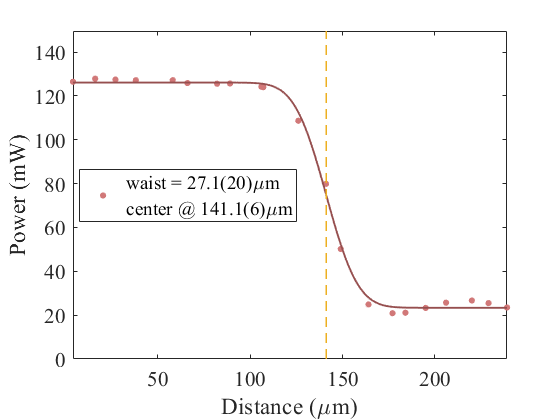


%% 拟合: '无标题拟合 1'。
[xData, yData] = prepareCurveData( x, y );

% 设置 fittype 和选项。
ft = fittype( 'a*erf(sqrt(2)*(x-u)/w)+c', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [-100 20 250 30];   % a c u w
opts.Lower = [-1000 0 0 0];   % a c u w

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );
u = fitresult.u;
w = fitresult.w;
interval = confint(fitresult);
us = (interval(2,3)-interval(1,3))/4;
ws = (interval(2,4)-interval(1,4))/4;

% 绘制数据拟合图。
f1 = figure; hold on;
l1 = plot( fitresult, xData, yData );   % [点 线]
l1(1).MarkerSize = 16;
l1(1).Color = [0.82 0.47 0.47];
l1(2).LineWidth = 1.4;
l1(2).Color = [0.59 0.31 0.31];

l2 = plot([u u],[ymin ymax],'--','Color',[0.93,0.69,0.13],'LineWidth',1.2);

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel( 'Distance (\mum)' );
ylabel('Power (mW)');
legend(['waist = ',num2str(w,'%.1f'),'(',num2str(ws*1e1,'%.0f'),')','\mum','\newline',...
    'center @ ',num2str(u,'%.1f'),'(',num2str(us*1e1,'%.0f'),')','\mum'],'','',...
    'Location','best');
grid off;
box on;

set(gca,'FontSize',16,'FontName','Times New Roman');
set(f1,'Visible','on');

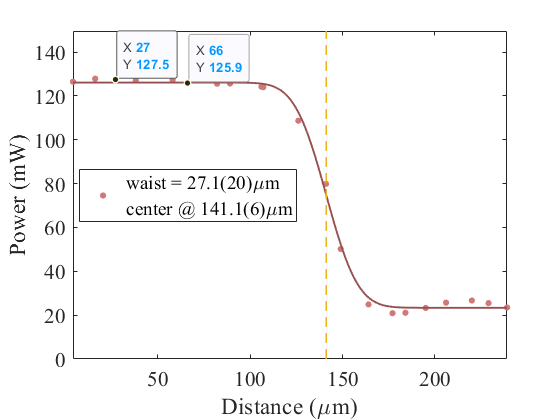


if save_data == 1
    savefig(f1,[maindir,'A_M1.fig']);
    saveas(f1,[maindir,'A_M1.png']);
    %
    save([maindir,'A_M1.mat']);
end


%_evening
